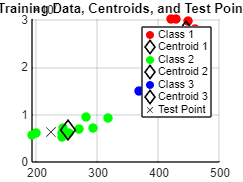

% clearvars; close all; clc;
% 
% % Cargar el dataset guardado
% load('features_and_labels.mat');
% 
% % Cargar matriz adicional de características de prueba
% % Matriz: testFeatures (dimensiones D x N_test)
% % Variable: testIDs (vector 1 x N_test con los IDs de cada señal de prueba)
% load('test_features_and_ids.mat', 'testFeatures', 'testIDs');  % Asegúrate de crear este archivo
% 
% N_train = 7;  % Número de vectores por clase para entrenamiento
% 
% % Inicializar centroides
% numClasses = max(allLabels);  % Número de clases (únicos en allLabels)
% m = zeros(size(allFeatures, 1), numClasses);  % Matriz de centroides
% S = eye(size(allFeatures, 1));  % Matriz identidad de covarianza
% 
% % Calcular centroides para cada clase
% for c = 1:numClasses
%     % Índices de la clase actual
%     idxClass = find(allLabels == c);  
%     idxTrain = idxClass(1:N_train);  % Primeros N_train como entrenamiento
% 
%     % Calcular el centroide
%     m(:, c) = mean(allFeatures(:, idxTrain), 2);
% end
% 
% % Visualización de puntos de entrenamiento
% figure; hold on; grid on;
% colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k'};
% for c = 1:numClasses
%     % Graficar puntos por clase
%     idxClass = find(allLabels == c);
%     scatter(allFeatures(1, idxClass), allFeatures(2, idxClass), 50, colors{c}, 'DisplayName', ['Class ' num2str(c)]);
%     % Graficar centroides
%     plot(m(1, c), m(2, c), 'kd', 'MarkerSize', 10, 'DisplayName', ['Centroid ' num2str(c)]);
% end
% title('Training Data and Centroids');
% legend();
% 
% % Clasificar puntos de prueba usando la matriz externa
% X_test = testFeatures;  % Matriz de características de prueba
% class_test = testIDs;   % IDs reales de las señales de prueba
% 
% predicted_labels = zeros(1, size(X_test, 2));
% class_val = zeros(numClasses, size(X_test, 2));  % Etiquetas de prueba en formato binario
% class_vtrue = zeros(numClasses, size(X_test, 2));  % Etiquetas predichas en formato binario
% 
% % Figura para graficar las distancias
% figure; hold on; grid on;
% for c = 1:numClasses
%     % Graficar puntos de prueba por clase
%     idxClass = find(class_test == c);
%     scatter(X_test(1, idxClass), X_test(2, idxClass), 50, colors{c}, 'o', 'DisplayName', ['Class ' num2str(c)]);
% end
% 
% for i = 1:size(X_test, 2)
%     X = X_test(:, i);
%     % Distancias a los centroides
%     d = zeros(1, numClasses);
%     for c = 1:numClasses
%         d(c) = sqrt((X - m(:, c))' * inv(S) * (X - m(:, c))); 
%     end
%     [~, predicted_labels(i)] = min(d);  % Clase más cercana
% 
%     % Convertir etiquetas a formato binario para plotconfusion
%     class_vtrue(predicted_labels(i), i) = 1;
%     class_val(class_test(i), i) = 1;
% 
%     % Graficar línea entre el punto de prueba y su centroide más cercano
%     line([X(1) m(1, predicted_labels(i))], [X(2) m(2, predicted_labels(i))], ...
%         'LineStyle', '--', 'Color', [1, 0, 0]);  % Línea en color rojo punteada
% end
% 
% % Añadir título y leyenda a la gráfica
% title('Test Points and Nearest Centroid Distances');
% legend();
% 
% % Matriz de confusión gráfica
% figure;
% plotconfusion(class_vtrue, class_val);
% 
% fprintf('El ID de la señal es: %d\n', class_vtrue(1,1));
% 
% 
% % Mostrar precisión en consola
% accuracy = sum(diag(confusionmat(class_test, predicted_labels))) / length(class_test) * 100;
% fprintf('Accuracy: %.2f%%\n', accuracy);
% 


clearvars; close all; clc;

% Cargar el dataset guardado
load('features_and_labels.mat');

% Cargar matriz adicional de características de prueba
load('test_features_and_ids.mat', 'testFeatures', 'testIDs');  % Archivo con señales de prueba e IDs

N_train = 7;  % Número de vectores por clase para entrenamiento

% Inicializar centroides
numClasses = max(allLabels);  % Número de clases (únicos en allLabels)
m = zeros(size(allFeatures, 1), numClasses);  % Matriz de centroides
S = eye(size(allFeatures, 1));  % Matriz identidad de covarianza

% Calcular centroides para cada clase
for c = 1:numClasses
    % Índices de la clase actual
    idxClass = find(allLabels == c);  
    idxTrain = idxClass(1:N_train);  % Primeros N_train como entrenamiento
    
    % Calcular el centroide
    m(:, c) = mean(allFeatures(:, idxTrain), 2);
end

% Visualización de puntos de entrenamiento
figure; hold on; grid on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k'};
testColor = 'k';  % Color de los puntos de prueba
testMarker = 'x';  % Marcador para los puntos de prueba

% Graficar puntos de entrenamiento y centroides
for c = 1:numClasses
    % Graficar puntos por clase
    idxClass = find(allLabels == c);
    scatter(allFeatures(1, idxClass), allFeatures(2, idxClass), 50, colors{c}, 'filled', 'DisplayName', ['Class ' num2str(c)]);
    % Graficar centroides
    plot(m(1, c), m(2, c), 'kd', 'MarkerSize', 10, 'LineWidth', 1.5, 'DisplayName', ['Centroid ' num2str(c)]);
end

% Clasificar puntos de prueba usando la matriz externa
X_test = testFeatures;  % Matriz de características de prueba
class_test = testIDs;   % IDs reales de las señales de prueba

predicted_labels = zeros(1, size(X_test, 2));
class_val = zeros(numClasses, size(X_test, 2));  % Etiquetas de prueba en formato binario
class_vtrue = zeros(numClasses, size(X_test, 2));  % Etiquetas predichas en formato binario

% Graficar puntos de prueba
for i = 1:size(X_test, 2)
    X = X_test(:, i);
    % Distancias a los centroides
    d = zeros(1, numClasses);
    for c = 1:numClasses
        d(c) = sqrt((X - m(:, c))' * inv(S) * (X - m(:, c))); 
    end
    [~, predicted_labels(i)] = min(d);  % Clase más cercana

    % Convertir etiquetas a formato binario para plotconfusion
    class_vtrue(predicted_labels(i), i) = 1;
    class_val(class_test(i), i) = 1;

    % Graficar punto de prueba
    scatter(X(1), X(2), 100, testColor, testMarker, 'DisplayName', 'Test Point');
end

% Añadir título y leyenda
title('Training Data, Centroids, and Test Points');
legend();
grid on;

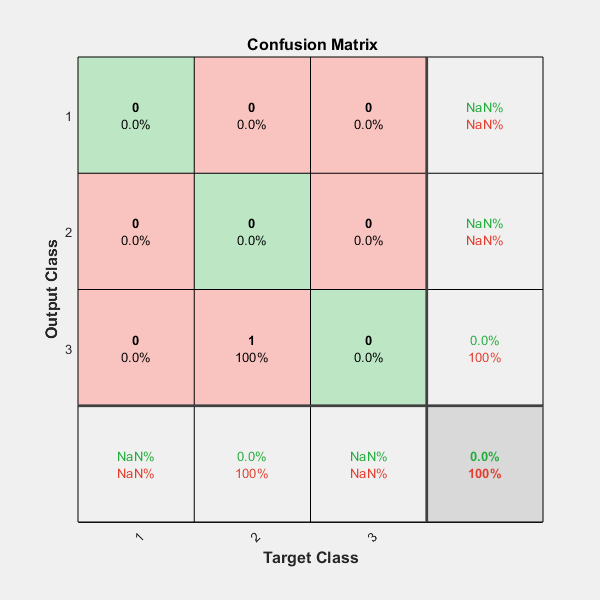


% Matriz de confusión gráfica
figure;
plotconfusion(class_vtrue, class_val);


% Mostrar precisión en consola
accuracy = sum(diag(confusionmat(class_test, predicted_labels))) / length(class_test) * 100;
fprintf('Accuracy: %.2f%%\n', accuracy);

Accuracy: 0.00%





% 
% clearvars; close all; clc;
% 
% % Cargar el dataset guardado
% load('features_and_labels.mat');
% 
% N_train = 7;  % Número de vectores por clase para entrenamiento
% 
% % Inicializar centroides
% numClasses = max(allLabels);  % Número de clases (únicos en allLabels)
% m = zeros(size(allFeatures, 1), numClasses);  % Matriz de centroides
% S = eye(size(allFeatures, 1));  % Matriz identidad de covarianza
% 
% % Calcular centroides para cada clase
% for c = 1:numClasses
%     % Índices de la clase actual
%     idxClass = find(allLabels == c);  
%     idxTrain = idxClass(1:N_train);  % Primeros N_train como entrenamiento
% 
%     % Calcular el centroide
%     m(:, c) = mean(allFeatures(:, idxTrain), 2);
% end
% 
% % Visualización de puntos de entrenamiento
% figure; hold on; grid on;
% colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k'};
% for c = 1:numClasses
%     % Graficar puntos por clase
%     idxClass = find(allLabels == c);
%     scatter(allFeatures(1, idxClass), allFeatures(2, idxClass), 50, colors{c}, 'DisplayName', ['Class ' num2str(c)]);
%     % Graficar centroides
%     plot(m(1, c), m(2, c), 'kd', 'MarkerSize', 10, 'DisplayName', ['Centroid ' num2str(c)]);
% end
% 
% 
% title('Training Data and Centroids');
% legend();
% 
% % Clasificar puntos de prueba
% N_test = 10 - N_train;  % Restantes para prueba
% X_test = [];
% class_test = [];
% 
% for c = 1:numClasses
%     idxClass = find(allLabels == c);
%     idxTest = idxClass(N_train+1:end);  % Últimos para prueba
%     X_test = [X_test, allFeatures(:, idxTest)];
%     class_test = [class_test, c * ones(1, N_test)];
% end
% 
% predicted_labels = zeros(1, size(X_test, 2));
% class_val = zeros(numClasses, size(X_test, 2));  % Etiquetas de prueba en formato binario
% class_vtrue = zeros(numClasses, size(X_test, 2));  % Etiquetas predichas en formato binario
% 
% for i = 1:size(X_test, 2)
%     X = X_test(:, i);
%     % Distancias a los centroides
%     d = zeros(1, numClasses);
%     for c = 1:numClasses
%         d(c) = sqrt((X - m(:, c))' * inv(S) * (X - m(:, c))); 
%     end
%     [~, predicted_labels(i)] = min(d);  % Clase más cercana
% 
%     % Convertir etiquetas a formato binario para plotconfusion
%     class_vtrue(predicted_labels(i), i) = 1;
%     class_val(class_test(i), i) = 1;
% end
% 
% % Matriz de confusión gráfica
% figure;plotconfusion(class_vtrue, class_val);
% 
% % Mostrar precisión en consola
% accuracy = sum(diag(confusionmat(class_test, predicted_labels))) / length(class_test) * 100;
% fprintf('Accuracy: %.2f%%\n', accuracy);


% ---------------------------------------------------------------------
% ---------------------------------------------------------------------
% ---------------------------------------------------------------------

% 
% clearvars; close all; clc;
% 
% load('features_and_labels.mat');
% 
% N = 10;  % Cantidad de vectores de caracter�sticas por clase
% N_train = 7;  % Seleccionamos cantidad de vectores para entrenamiento
% 
% % Asignar numeros de 1 a 3 a las clases
% % class = ones(1,150);class(1,51:100)=2;class(1,101:end)=3;
% numClasses = max(allLabels);
% 
% % Se usan los primeros N_train para entrenamiento, esto es, estimar la
% % media y covarianza para cada clase usando s�lo las caracter�sticas 3 y 4
% 
% % m1=mean(irisInputs(3:4,1:N_train),2);  % Centroide de la clase C1
% % m2=mean(irisInputs(3:4,51:51+N_train),2); % Centroide de la clase C2
% % m3=mean(irisInputs(3:4,101:101+N_train),2); % Centroide de la clase C3 
% % 
% % m=[m1 m2 m3];
% % S = eye(2);
% 
% m = zeros(size(allFeatures, 1), numClasses);  % Matriz de centroides
% S = eye(size(allFeatures, 1));  % Matriz identidad de covarianza
% 
% % Calcular centroides para cada clase
% for c = 1:numClasses
%     % Índices de la clase actual
%     idxClass = find(allLabels == c);  
%     idxTrain = idxClass(1:N_train);  % Primeros N_train como entrenamiento
% 
%     % Calcular el centroide
%     m(:, c) = mean(allFeatures(:, idxTrain), 2);
% end
% 
% 
% %% Gr�fica de los puntos de entrenamiento
% % X1=[irisInputs(3,1:N_train) irisInputs(3,51:51+N_train) irisInputs(3,101:101+N_train)];
% % X2=[irisInputs(4,1:N_train) irisInputs(4,51:51+N_train) irisInputs(4,101:101+N_train)];
% % C = [class(1,1:N_train) class(1,51:51+N_train) class(1,101:101+N_train)];
% % 
% % scatter(X1,X2,30,C);
% % 
% % hold on;grid on;
% 
% % Visualización de puntos de entrenamiento
% figure; hold on; grid on;
% colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k'};
% for c = 1:numClasses
%     % Graficar puntos por clase
%     idxClass = find(allLabels == c);
%     scatter(allFeatures(1, idxClass), allFeatures(2, idxClass), 50, colors{c}, 'DisplayName', ['Class ' num2str(c)]);
%     % Graficar centroides
%     plot(m(1, c), m(2, c), 'kd', 'MarkerSize', 10, 'DisplayName', ['Centroid ' num2str(c)]);
% end
% title('Training Data and Centroids');
% legend();
% 
% 
% 
% %Grafica de las medias de cada clase
% % plot(m1(1),m1(2),'rd', 'MarkerSize',10);
% % plot(m2(1),m2(2),'rd','MarkerSize',10);
% % plot(m3(1),m3(2),'rd','MarkerSize',10);
% 
% % plot(m1(1),m1(2),'kd', 'MarkerSize',10);
% % plot(m2(1),m2(2),'bd','MarkerSize',10);
% % plot(m3(1),m3(2),'gd','MarkerSize',10);
% 
% %% Test
% 
% % X1_val=[irisInputs(3,N_train+1:50) irisInputs(3,51+N_train:100) irisInputs(3,101+N_train:end)];
% % X2_val=[irisInputs(4,N_train+1:50) irisInputs(4,51+N_train:100) irisInputs(4,101+N_train:end)];
% % L_val = (50-N_train);
% % 
% % class_val =zeros(3,L_val*3);
% % class_val(1,1:L_val)=1;
% % class_val(2,L_val+1:L_val*2)=1;
% % class_val(3,2*L_val+1:end)=1;
% % class_vtrue =zeros(3,L_val*3);
% 
% % Clasificar puntos de prueba
% N_test = 10 - N_train;  % Restantes para prueba
% X_test = [];
% class_test = [];
% 
% for c = 1:numClasses
%     idxClass = find(allLabels == c);
%     idxTest = idxClass(N_train+1:end);  % Últimos para prueba
%     X_test = [X_test, allFeatures(:, idxTest)];
%     class_test = [class_test, c * ones(1, N_test)];
% end
% 
% % for i=1:L_val*3
% %     X = [X1_val(i);X2_val(i)];
% % 
% %     %Calcula las distancias
% %     d1=sqrt((X-m1)'*inv(S)*(X-m1)); 
% %     d2=sqrt((X-m2)'*inv(S)*(X-m2)); 
% %     d3=sqrt((X-m3)'*inv(S)*(X-m3));
% %     [d,j1]=max(class_val(:,i));
% %     [d,j2]=min([d1 d2 d3]);
% %     class_vtrue(j2,i)=1;
% 
% predicted_labels = zeros(1, size(X_test, 2));
% for i = 1:size(X_test, 2)
%     X = X_test(:, i);
%     % Distancias a los centroides
%     d = zeros(1, numClasses);
%     for c = 1:numClasses
%         d(c) = sqrt((X - m(:, c))' * inv(S) * (X - m(:, c))); 
%     end
%     [~, predicted_labels(i)] = min(d);  % Clase más cercana
% end
% 
% % 
% %     %Grafica del punto de entrada con un color que depende de la clase
% %     switch j1
% %         case (1)
% %              plot(X(1),X(2),'k*');
% %         case (2)
% %              plot(X(1),X(2),'b*');
% %         otherwise
% %              plot(X(1),X(2),'g*');
% %     end
% %     %Grafica la distancia mas cercana
% %     line([X(1) m(1,j2)],[X(2) m(2,j2)],'LineStyle','--','Color',[1 0 0]);
% % end
% % 
% % hold on; xlabel('C1=Negro ; C2=azul; C3=verde ; En circulo clasificaci�n' );
% % title('Minima Distancia en IrisDataset');
% % figure;plotconfusion(class_vtrue,class_val);
% 
% 